# Inner Controller Development

## Setup

load 'quad_copter_models.mat';
USE_REAL_DATA = true;

We want to develop the fastest controller for the system that we can possibly get. This is a two step process. First we increase the bandwidth of the innner system to the limit and then work on the outer controller. Before we start we need to devise a reference model.

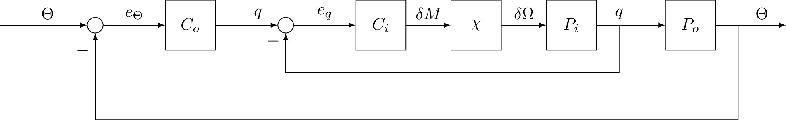

We have a set of I/O data measured from the input of the `PitchRateModel` bock to it's output. The input is $\delta \Omega$, the difference between the speeds of the front and rear propellers. For more information on the origin of this choice read [this](http://thesis.comkieffer.com/making-sense-of-the-data.html) article. Since writing that article the data has been processed to convert it to absolute values. The output is the angular velocity of the quad copter. 

However we  have chosen to consider the `Mixer` and the `PitchRateModel` as a single `Plant` block for the VRFT to remove the effect of the Mixer from the controller. 

PlantModel = PitchRateModel * Mixer; 
PlantModel_dt = c2d(PlantModel, Ts); 

## Reference Model. 

There is no sense in using a complex model. The simplest model that lets us tune damping and bandwidth seperatly is a 2nd order model. We will start with a low cut-off frequency and move up until we reach the upper limit. 

Note: at this time we are neglecting the effect of noise on the data and pretending that the model has no delay. The closed loop system has some delay (about 40ms or 4 samples) however the open loop data we have can be considered delay-free.

InnerReferenceModel = mk_2nd_order(10, .7);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);

## Looking at the data

vrft_data = struct();
ol_data = load('dati_id_ol_scalati.mat');

vrft_data.time      = ol_data.t;
vrft_data.dOmega    = ol_data.u;
vrft_data.q_dot     = ol_data.yi;
vrft_data.type      = 'Experimental';


The data we have goes from $\delta \Omega$ to $\dot{q}$. However, for the VRFT, we want the data from $\delta M$to $\dot{q}$. This means that we need to include the effect of the `Mixer` in the data. Since the Mixer is upstream  of our input we have:


$$d\Omega = \Phi \cdot d M \rightarrow d M = \Phi^{-1} \cdot d\Omega$$


vrft_data.dM = lsim(Mixer^-1, vrft_data.dOmega, vrft_data.time);
vrft_data.q_dot_sim = lsim(PlantModel, vrft_data.dM, vrft_data.time);

Let's take a look at what we have.

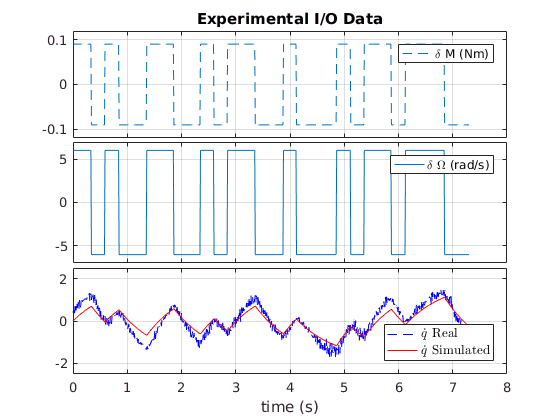

figure()
    subplot 311
        plot(vrft_data.time, vrft_data.dM, '--'); 
        legend('\delta M (Nm)'); ylim([-.12, .12]);
        title('Experimental I/O Data');
        
    subplot 312 
        plot(vrft_data.time, vrft_data.dOmega); 
        legend('\delta \Omega (rad/s)'); ylim([-7, 7]);
    subplot 313
        plot(vrft_data.time, vrft_data.q_dot, '--b', ...
             vrft_data.time, vrft_data.q_dot_sim, 'r'); 
        legend({'$$\dot{q}$$ Real', '$$\dot{q}$$ Simulated'}, ...
            'Location', 'southEast', 'Interpreter', 'latex', 'FontSize', 10); 
        xlabel('time (s)'); ylim([-2.5, 2.5]);
condense_subplots('tight', true)        

We are most interested in the third plot. This plot shows the real (measured) angular velocity ($\dot{q}$) and the simulatedangular velocity. These two values seem to be in accordance. So far, so good.

## VRFT Time !

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

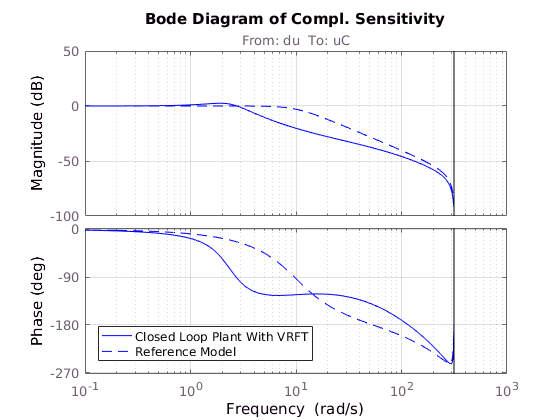

[OptimalInnerController, Theta] = ...
    VRFT1_ry_theta(vrft_data.dM, vrft_data.q_dot, InnerReferenceModel_dt, PIDControllerClass_dt, [], [], []);
    

cloop = loopsens(PlantModel_dt, OptimalInnerController); 
InnerLoop_VRFT = cloop.Ti;

figure()
    bode(InnerLoop_VRFT, 'b', InnerReferenceModel_dt, 'b--');
    title('Bode Diagram of Compl. Sensitivity');
    legend('Closed Loop Plant With VRFT', 'Reference Model', 'location', 'SouthWest');
    grid on;

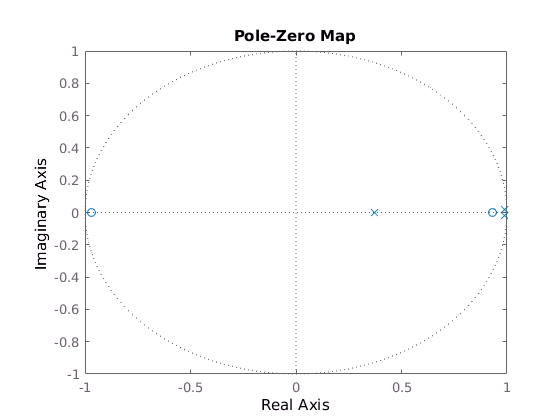

    
figure()
    pzmap(InnerLoop_VRFT)

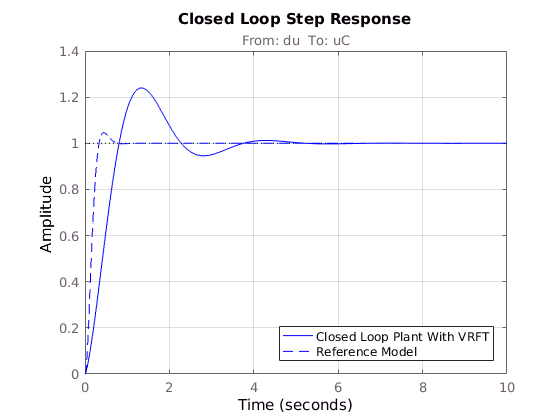

    
figure()
    step(InnerLoop_VRFT, 'b', InnerReferenceModel_dt, '--b', 10);
    title('Closed Loop Step Response');
    legend('Closed Loop Plant With VRFT', 'Reference Model', 'location', 'SouthEast');
    grid on;    

For convenience we will save some of the data we used here. In the outer VRFT we will need access to the input and output signals we used to generate the inner controller. We will also keep a copy of the generated controller for obvious reasons.

save('quad_copter_models.mat', ...
    'OptimalInnerController', 'vrft_data', 'InnerLoop_VRFT', ...
    'InnerReferenceModel_dt', 'PlantModel', 'PlantModel_dt', 'USE_REAL_DATA', '-append');